% ===== 多级带级间冷却的轴流式压缩机测试代码=====
% 系统参数
N_stage = 5;                            % 级数
pressure_drop_ratio = 0.02;             % 级间压力损失比例

% 第一级压缩机入口参数
T_in1 = 300;                            % 入口温度 (K)
P_in1 = 101325;                         % 入口压力 (Pa)
m = 50;                                 % 空气质量流量 (kg/s)
c_in1 = 100;                            % 入口速度 (m/s)

% 各级压缩机参数
epsilon_list = [2, 1.8, 1.5, 1.4, 1.3];         % 压比分配
eta_ad_list = [0.92, 0.90, 0.88, 0.87, 0.86];       % 绝热效率

% 各级换热器参数
T_cold_in_list = [280, 285, 290, 295, 300];       % 冷却水入口温度 (K)
m_dot_cold_list = [100, 100, 100, 100, 100];      % 冷却水流量 (kg/s)
cp_cold_list = [4180, 4180, 4180, 4180, 4180];      % 冷却水比热容 [J/(kg·K)]
P_cold_list = [101325, 101325, 101325, 101325, 101325];  % 冷却水压力 (Pa)
U_list = [500, 500, 500, 500, 500];               % 传热系数 [W/(m²·K)]
A_list = [100, 100, 100, 100, 100];               % 传热面积 (m²)
HX_type_list = {'counterflow', 'counterflow', 'counterflow',  'counterflow',  'counterflow'};

% 气体常数 (空气)
R = 287;                                % 气体常数 [J/(kg·K)]
k = 1.4;                                % 绝热指数
Cp = 1005;                              % 定压比热容 [J/(kg·K)]

% 运行系统
system_result = multi_stage_compressor_system(...
    N_stage, T_in1, P_in1, m, c_in1, ...
    epsilon_list, eta_ad_list, ...
    T_cold_in_list, m_dot_cold_list, cp_cold_list, P_cold_list, ...
    U_list, A_list, HX_type_list, ...
    R, k, Cp, pressure_drop_ratio);


--- 第 1 级计算开始 ---
压缩机1计算: 入口温度=300.00K, 入口压力=101325.00Pa
压缩机1输出: 出口温度=371.42K, 出口压力=202650.00Pa
级间压力损失: 4053.00Pa
换热器1计算: 气体入口=371.42K, 冷却水入口=280.00K
换热器1输出: 气体出口=315.28K, 冷却水出口=286.75K, 换热量=2820.86kW
下一级压缩机入口: 温度=315.28K, 压力=198597.00Pa

--- 第 2 级计算开始 ---
压缩机2计算: 入口温度=315.28K, 入口压力=198597.00Pa
压缩机2输出: 出口温度=379.34K, 出口压力=357474.60Pa
级间压力损失: 7149.49Pa
换热器2计算: 气体入口=379.34K, 冷却水入口=285.00K
换热器2输出: 气体出口=321.41K, 冷却水出口=291.96K, 换热量=2911.06kW
下一级压缩机入口: 温度=321.41K, 压力=350325.11Pa

--- 第 3 级计算开始 ---
压缩机3计算: 入口温度=321.41K, 入口压力=350325.11Pa
压缩机3输出: 出口温度=366.27K, 出口压力=525487.66Pa
级间压力损失: 10509.75Pa
换热器3计算: 气体入口=366.27K, 冷却水入口=290.00K
换热器3输出: 气体出口=319.43K, 冷却水出口=295.63K, 换热量=2353.43kW
下一级压缩机入口: 温度=319.43K, 压力=514977.91Pa

--- 第 4 级计算开始 ---
压缩机4计算: 入口温度=319.43K, 入口压力=514977.91Pa
压缩机4输出: 出口温度=356.48K, 出口压力=720969.07Pa
级间压力损失: 14419.38Pa
换热器4计算: 气体入口=356.48K, 冷却水入口=295.00K
换热器4输出: 气体出口=318.73K, 冷却水出口=299.54K, 换热量=1897.22kW
下一级压缩机入口: 温度=318.73K, 压力=706549.69Pa

--- 第 5 级计算开始 ---
压缩机5计算: 入口温度=318.73K, 入

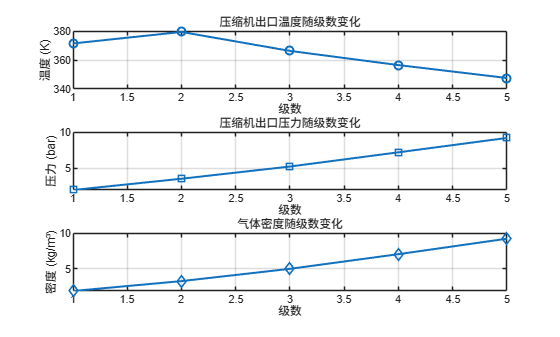


% 提取物性参数变化
stage_num = 1:N_stage;
T_out_comp = cellfun(@(x) x.T_out, system_result.compressor_results);
P_out_comp = cellfun(@(x) x.P_out, system_result.compressor_results);
T_out_hx = system_result.heat_exchanger_results.T_hot_out;

% 绘制物性参数变化曲线
figure;
subplot(3,1,1)
plot(stage_num, T_out_comp, 'o-', 'LineWidth', 1.5)
title('压缩机出口温度随级数变化');
xlabel('级数'); ylabel('温度 (K)'); grid on;

subplot(3,1,2)
plot(stage_num, P_out_comp/1e5, 's-', 'LineWidth', 1.5)
title('压缩机出口压力随级数变化');
xlabel('级数'); ylabel('压力 (bar)'); grid on;

subplot(3,1,3)
rho = P_out_comp./(R*T_out_comp);  % 密度计算 ρ = P/(RT)
plot(stage_num, rho, 'd-', 'LineWidth', 1.5)
title('气体密度随级数变化');
xlabel('级数'); ylabel('密度 (kg/m³)'); grid on;